## LOAD

clear; clc;

load('effshift.mat')
root_path = "D:\demos\mat_demos\spectral_analysis\essay2\extraction";
mats = dir(fullfile(root_path, '*.mat'));

for i = 1:length(mats)
    mat_name = strcat('r', mats(i).name(1:end-4));
    eval([mat_name, ' = load(fullfile(root_path, mats(i).name)).avedata;'])
end

## COMBINE

X_pretreatment = []; 

orders = ["tftft", "ftftf"]; 
nums = linspace(1,20,20)*25;

for index = 1:length(nums)
    num = nums(index);
    if mod(num, 50) == 0
        order = orders(2);
    else 
        order = orders(1);
    end
    
    avedata = eval(strcat('r', num2str(num)));
    X_pretreatment = [X_pretreatment; avedata];
end

y_extraction = [];

label_tftft_matric = [1, 3, 5, 7, 9;
               4, 6, 8,10, 2;
               5, 7, 9, 1, 3;
               8,10, 2, 4, 6;
               9, 1, 3, 5, 7]

label_tftft_matric =      1     3     5     7     9
     4     6     8    10     2
     5     7     9     1     3
     8    10     2     4     6
     9     1     3     5     7


lebel_tftft = reshape(label_tftft_matric, 25, 1)

lebel_tftft =      1
     4
     5
     8
     9
     3
     6
     7
    10
     1


label_ftftf_matric = [2, 4, 6, 8,10;
               3, 5, 7, 9, 1;
               6, 8,10, 2, 4;
               7, 9, 1, 3, 5;
               10,2, 4, 6, 8];
lebel_ftftf = reshape(label_ftftf_matric, 25, 1);

y_extraction = repmat([lebel_tftft; lebel_ftftf], 10, 1);

## PREPROCESSING

tic
X_air = pre_airpls(X_extraction, 10e3);

X_air_sg = pre_sgfilter(X_air, 7);

X_air_sg_v = reshape(X_air_sg, 1, size(X_air_sg, 1)*size(X_air_sg, 2));
X_air_sg_norm_v = mapminmax(X_air_sg_v, 0, 1);
X_air_sg_norm = reshape(X_air_sg_norm_v, size(X_air_sg, 1), size(X_air_sg, 2));
toc

历时 0.096760 秒。



X_pretreatment = X_air_sg_norm;

!!! try all pretreatments after variale selection 

## PLOT

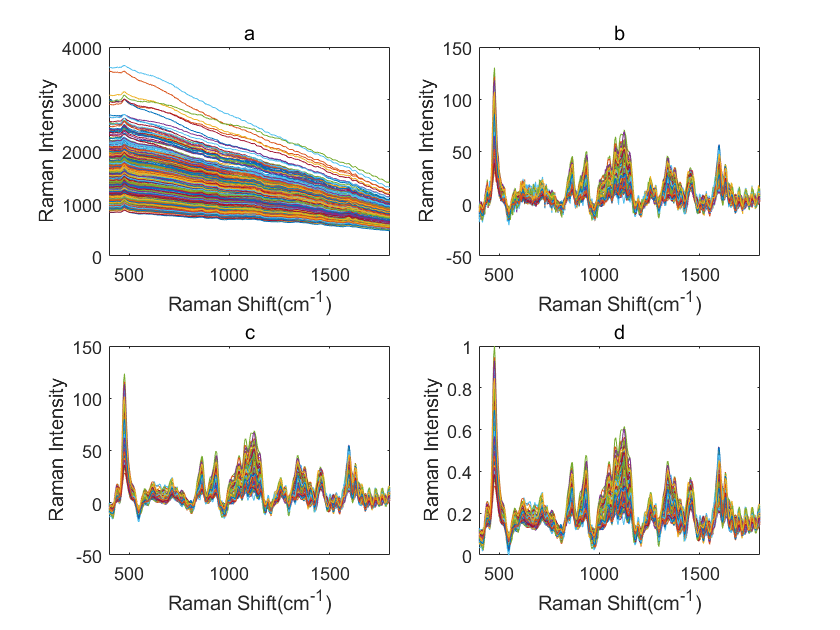

figure;
subplot(2,2,1);
for k = 1:size(X_extraction, 1)
    plot(effshift, X_extraction(k, :));
    hold on;
end 
xlim([400, 1800])
xlabel('Raman Shift(cm^{-1})')
ylabel('Raman Intensity')
title('a')

subplot(2,2,2);
for k = 1:size(X_air, 1)
    plot(effshift, X_air(k, :));
    hold on;
end 
xlim([400, 1800])
xlabel('Raman Shift(cm^{-1})')
ylabel('Raman Intensity')
title('b')

subplot(2,2,3);
for k = 1:size(X_air_sg, 1)
    plot(effshift, X_air_sg(k, :));
    hold on;
end
xlim([400, 1800])
xlabel('Raman Shift(cm^{-1})')
ylabel('Raman Intensity')
title('c')

subplot(2,2,4);
for k = 1:size(X_pretreatment, 1)
    plot(effshift, X_air_sg_norm(k, :));
    hold on;
end 
xlim([400, 1800])
xlabel('Raman Shift(cm^{-1})')
ylabel('Raman Intensity')
title('d')

y1 = find(y_extraction == 1); 
y2 = find(y_extraction == 2);
y3 = find(y_extraction == 3);
y4 = find(y_extraction == 4);
y5 = find(y_extraction == 5); 
y6 = find(y_extraction == 6);
y7 = find(y_extraction == 7);
y8 = find(y_extraction == 8);
y9 = find(y_extraction == 9);
y10 = find(y_extraction == 10);

data = X_pretreatment;
avedata_variety = zeros(8, length(effshift));

avedata_variety(1, :) = mean(data(y1, :), 1);
avedata_variety(2, :) = mean(data(y2, :), 1);
avedata_variety(3, :) = mean(data(y3, :), 1);
avedata_variety(4, :) = mean(data(y4, :), 1);
avedata_variety(5, :) = mean(data(y5, :), 1);
avedata_variety(6, :) = mean(data(y6, :), 1);
avedata_variety(7, :) = mean(data(y7, :), 1);
avedata_variety(8, :) = mean(data(y8, :), 1);
avedata_variety(9, :) = mean(data(y9, :), 1);
avedata_variety(10, :) = mean(data(y10, :), 1);

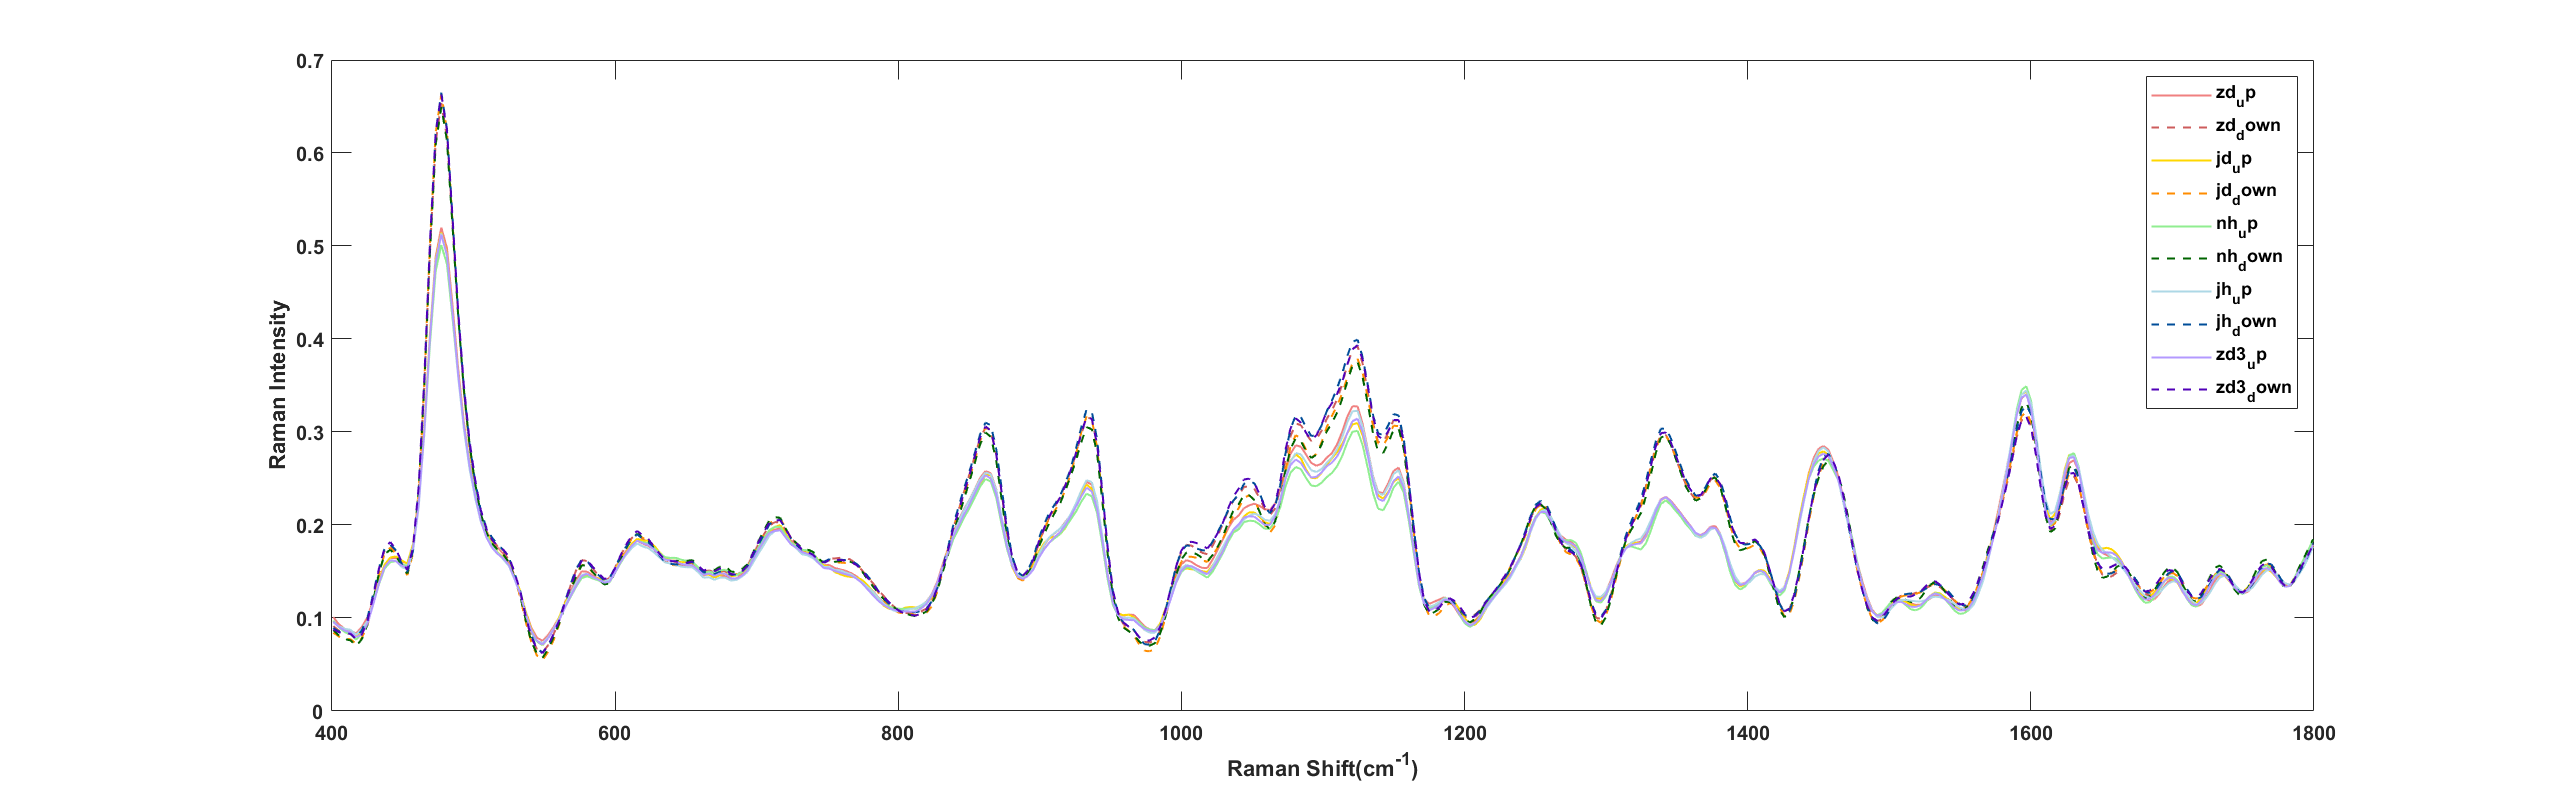

figure('Units','normalized','Position',[0, 0, 1, 0.5]);
seed_varieties = ["zd_up", "zd_down",... 
                  "jd_up", "jd_down",... 
                  "nh_up", "nh_down",... 
                  "jh_up", "jh_down",...
                  "zd3_up", "zd3_down"];
colors = ["#F08080", "#CD5C5C",... 
          "#FFD700", "#FF8C00",... 
          "#90EE90", "#006400",... 
          "#ADD8E6", "#004D99",...
          "#B399FF", "#5000B8"];

for k = 1:length(seed_varieties)
    if mod(k, 2) == 0
        plot(effshift, avedata_variety(k, :), "LineStyle", '--', "Color", colors(k), "LineWidth", 1);
    else
        plot(effshift, avedata_variety(k, :), "Color", colors(k), "LineWidth", 1);
    end    
    hold on;
end

xlim([400, 1800])
xlabel('Raman Shift(cm^{-1})')
ylabel('Raman Intensity')
legend(seed_varieties) 
set(gca,'fontsize',10, 'FontWeight','bold');